% Quadratic elements
clc,clearvars,format compact,close all
E = input("Young's Modulus of bar material: ");
l = input("Length of bar: ");
A_l = input("cross section Area at the free end: ");
P = input("Value of force applied at end: ");
n = input("Input array of no. of Quadratic elements to discretize: ");
disp_end_quad = [];
for i = 1:length(n)
 e_n = zeros(n(i),3); %element node connectivity relation

 v = 1;
 for j = 1:n(i)
 e_n(j,:) = [v v+1 v+2]; %i th row gives i th element's node connectivity
 v = v+2;
 end
 l_e = l/n(i); %Length of each element
 no_nodes = max(e_n,[],'all'); %no. of nodes
 force = zeros(no_nodes,1);
 stiffness = zeros(no_nodes);
 displacement = zeros(no_nodes,1);

 g = 1;
 h = setdiff(1:no_nodes,g);
 r = no_nodes;
 force(r,1) = P;
 reduced_force = force(h, :);
 %Creating Stiffness matrix
 for j = 1:n(i)

 t = 3 - (((2*j)-1)/n(i));
 T = (E*A_l*t)/(3*l_e);
 q = e_n(j,1); % left node no. of element j
 r = e_n(j,2); % middle node no. of element j
 s = e_n(j,3); % right node no. of element j
 %Diagonal elements
 stiffness(q,q) = stiffness(q,q) + (7*T);
 stiffness(r,r) = stiffness(r,r) + (16*T);
 stiffness(s,s) = stiffness(s,s) + (7*T);

 %Upper diagonal elements
 stiffness(q,r) = stiffness(r,s) - (8*T);
 stiffness(q,s) = stiffness(s,r) + T;
 stiffness(r,s) = stiffness(r,s) - (8*T);

 %Lower diagonal elements
 stiffness(r,q) = stiffness(q,r);
 stiffness(s,q) = stiffness(q,s);
 stiffness(s,r) = stiffness(r,s);

 end
 zero_disp_nodes = g;
 active_nodes = setdiff(1:no_nodes,zero_disp_nodes); % nodes with unknown displacement
 reduced_stiffness = stiffness;
 reduced_stiffness = reduced_stiffness(:,active_nodes); %A([3,9],:) =[]; Deletes rows
 reduced_stiffness = reduced_stiffness(active_nodes,:); %keeps rows and columns of active nodes in stifness matrix in order to solve for unknown displacements.
 unknown_disp = inv(reduced_stiffness)*reduced_force;
 for j = 1:length(active_nodes)
 displacement(active_nodes(j)) = unknown_disp(j);
 end
 fprintf("\n%d Quadratic elements", n(i))
 fprintf("\nDisplacement at end = %d", displacement(no_nodes))
 disp_end_quad(end+1) = displacement(no_nodes);
end

2 Quadratic elements


Displacement at end = 5.333333e-03

4 Quadratic elements


Displacement at end = 5.448773e-03

6 Quadratic elements


Displacement at end = 5.472906e-03

8 Quadratic elements


Displacement at end = 5.481624e-03

10 Quadratic elements


Displacement at end = 5.485710e-03

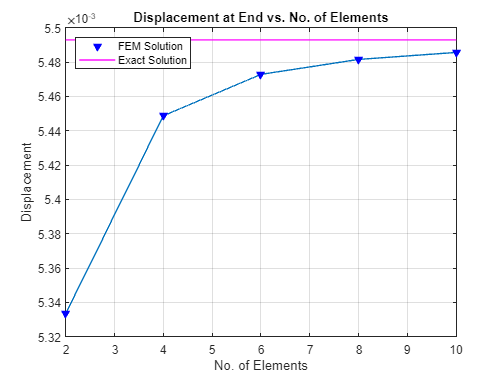

%Plotting
X = n;
Y = disp_end_quad;
plot(X,Y);
hold on
plot(X,Y,'bv','MarkerFaceColor','b');
title('Displacement at End vs. No. of Elements')
ylabel('Displacement')
xlabel('No. of Elements')
grid on
analy_soln = (P*l*log(3))/(2*E*A_l);
yline(analy_soln,'m','LineWidth',1.5)
legend('','FEM Solution','Exact Solution','Location','Northwest','Orientation','vertical');